[y_source, fs] = audioread("arthur_clip_48k.wav");

% load('new_irs.mat')
% source_foam = measurementData(1, 2).ImpulseResponse
% source = measurementData(2, 2).ImpulseResponse
% panel = measurementData(3, 2).ImpulseResponse

source_foam = irdata_141630(1, 2).ImpulseResponse

source_foam = struct with fields:
         Time: [192000×1 double]
    Amplitude: [192000×1 double]


source = irdata_141630(2, 2).ImpulseResponse

source = struct with fields:
         Time: [192000×1 double]
    Amplitude: [192000×1 double]


panel = irdata_141630(3, 2).ImpulseResponse

panel = struct with fields:
         Time: [192000×1 double]
    Amplitude: [192000×1 double]


% the source IR picks up both the direct IR and the reflection
s = source.Amplitude;
g = source_foam.Amplitude;
k = panel.Amplitude;
h = s - g;

[k_max, k_idx] = max(abs(k))

k_max = 0.0714

k_idx = 3317

[s_max, s_idx] = max(abs(s))

s_max = 0.0282

s_idx = 3382

[h_max, h_idx] = max(abs(h))

h_max = 0.0289

h_idx = 3382

scale_h = k_max / h_max

scale_h = 2.4710

scale_s = k_max / s_max

scale_s = 2.5335


source_scale = 1;
panel_scale_h = source_scale / scale_h

panel_scale_h = 0.4047

panel_scale_s = source_scale / scale_s

panel_scale_s = 0.3947

function f = inverseIR(panelIR, sourceIR, Lf, lamda)
    k = panelIR(:);
    h = sourceIR(:);
    
    K = convmtx(k, Lf);
    size(K)
    Lh = length(h);

    K = K(1:Lh, :);
    y = -h(1:Lh);
    size(K)
    
    % f = (KK.T)^-1 K.Ty
    % (KK.T)f = K.Ty
    f = (K.'*K + lamda*eye(Lf)) \ (K.'*y);
end

lamda = 1e-3;
Lf = 1024;

f_h = inverseIR(k, h, Lf, lamda);

ans =       193023        1024


ans =       192000        1024


f_s = inverseIR(k, s, Lf, lamda);

ans =       193023        1024


ans =       192000        1024


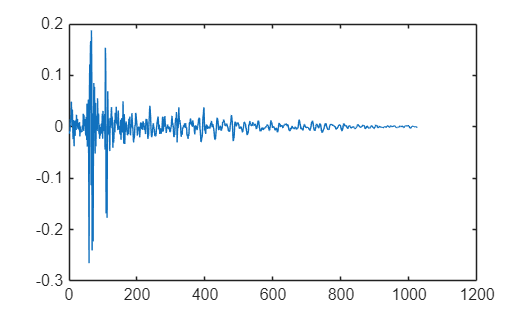

figure
plot(f_h)

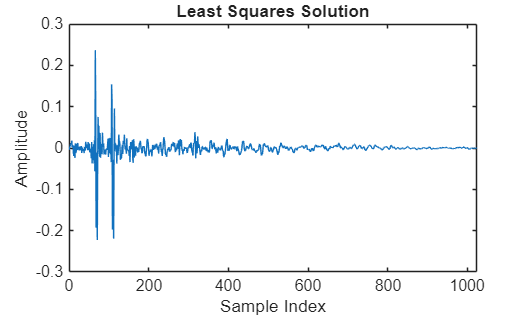


figure
plot(f_s)
xlim([0, length(f_s)])
title("Least Squares Solution")
xlabel("Sample Index")
ylabel("Amplitude")

h_hat = -conv(k, f_h);
res = h - h_hat(1:length(h));
mse_h = mean(res .* res)

mse_h = 3.7132e-09


s_hat = -conv(k, f_s);   % predicted cancellation
res = s - s_hat(1:length(s));
mse_s = mean(res .* res)

mse_s = 1.9528e-09

y = conv(k, f_s);
% y = y(1:length(y_source));
kfx = conv(y, y_source);
kfx = kfx(1:length(y_source));

hx = -conv(s, y_source);
hx = hx(1:length(y_source));

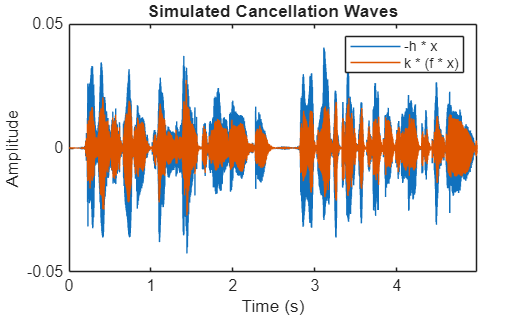

t = (0:length(y_source)-1) / fs;
t = t';
figure
plot(t, hx);
hold on
plot(t, kfx);
legend('-h * x', 'k * (f * x)')
title("Simulated Cancellation Waves")
xlabel('Time (s)')
ylabel('Amplitude')
xlim([t(1) t(end)])

err = kfx - hx;
mse_y = mean(err.^2)

mse_y = 2.7998e-05

x_s = conv(f_s, y_source);
x_h = conv(f_h, y_source);
zero_panel = 0 * y_source;

size(x_s)

ans =       239857           1


size(x_h)

ans =       239857           1


size(zero_panel)

ans =       238834           1


% potentially start at Lf / 2 instead of 1

x_s = x_s(1:length(y_source), :);
x_h = x_h(1:length(y_source), :);

out_s = [x_s, y_source];
out_h = [x_h, y_source];

no_cancel = [zero_panel, y_source];

size(out_s)

ans =       238834           2


size(out_h)

ans =       238834           2


size(no_cancel)

ans =       238834           2



audiowrite("no_cancel.wav", no_cancel, fs);
audiowrite("cancel_s.wav", out_s, fs);
audiowrite("cancel_h.wav", out_h, fs);